tic
delete(gcp('nocreate'))
parpool ('local',12)

Starting parallel pool (parpool) using the 'local' profile ...
connected to 12 workers.

ans = 

 Pool - 属性: 

            Connected: true
           NumWorkers: 12
              Cluster: 

profile on
% try

%%初始环境参数
w=3*10^(-5);
d_initial=7.9.*10.^(-4);%%初始距离
v_drift=7.9*10^(-4);%%漂移流速
M=5.*10.^(4);       %%发送分子数量
%  D=2.42*10.^(-10);
 D=10.^(-9);    %%扩散系数  D=2.42*10.^(-10);
 Dr=5;               %%旋转扩散系数 
 v=1.975.*10^(-4);   %% 相对移动速度
%生成随机的bit位信息
block_length=9%%m每一块的长度

block_length = 9

block=700%%分块的个数

block = 700

num=block_length*block;%%原始信息长度
bit=rand(1,num);
bit(bit>0.5)=1;
bit(bit<=0.5)=2;
bit ; %%生成0~1随机数序列
B=encode_abc(bit,block_length);%% 信息编码成三分子
encode_a_b_c=B

encode_a_b_c =      3     2     1     1     1     2     1     2     2     2     3     2     1     1     1     2     2     2     2     2     3     2     2     2     1     1     1     2     2     2     3     2     2     1     1     2     1     2     2     1     3     1     2     1     2     2     1     1     1     2


%%【分别作出abc三种分子的编码】
encode_a=encode_a_b_c;
encode_b=encode_a_b_c;
encode_c=encode_a_b_c;
encode_a(encode_a~=1)=0 ;
encode_b(encode_b~=2)=0;
encode_b=encode_b/2;
encode_c(encode_c~=3)=0;
encode_c=encode_c/3;
%%一维移动性
example_time=0.02;
example_number=2./example_time; %% 每两秒钟的采样数40次
t1=0:example_time:3*length(encode_a_b_c)-example_time; %% 每一位2秒，再两倍时间长度，一共四倍
t2=0:example_time:40-example_time;  %%【注意，t2的长度会影响计算时长与阈值设置】
location=zeros(2,length(t1))%%二维位置

location =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


location(1,1)=7.9.*10.^(-4)

location =    1.0e-03 *

    0.7900         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    

%location(2,1)=7.9.*10.^(-4)

%【旋转游走距离变化】
theta=zeros(size(t1));
d_mobile=zeros(size(t1));
d_mobile(1)=d_initial;
rotation_angle=rand(1,length(t1));
rotation_angle(rotation_angle<=0.5)=-abs((2*Dr *example_time).^0.5);
rotation_angle(rotation_angle>0.5)=abs((2*Dr *example_time).^0.5);%%两个随机旋转的角度
theta(1)=rotation_angle(1);
for i=1:1:length(t1)-1
    theta(i+1)=theta(i)+rotation_angle(i);
    if location(1,i)+v*example_time*cos(theta(i))>0
        location(1,i+1)=location(1,i)+v*example_time*cos(theta(i));
    else
        theta(i+1)=theta(i)+rotation_angle(i)+pi;
        location(1,i+1)=location(1,i)+v*example_time*cos(theta(i));
    end
end
theta;
location;

for i=1:1:length(t1)-1
    if  location(2,i)+v*example_time*sin(theta(i))>w
        1;
        location(2,i+1)=w+[example_time-(w-location(2,i))/(sin(abs(theta(i)))*v)]*sin(-abs(theta(i)))*v;
    elseif location(2,i)+v*example_time*sin(theta(i))<0
        2;
        location(2,i+1)=[example_time-location(2,i)/(v*sin(abs(theta(i))))]*sin(abs(theta(i)))*v;
    end
end
location;

for i=1:1:length(t1)
    d_mobile(i)=[location(1,i)^2+location(2,i)^2]^0.5;
end
d_mobile

d_mobile =    1.0e-03 *

    0.7900    0.7936    0.7960    0.7969    0.7961    0.7936    0.7928    0.7903    0.7868    0.7844    0.7835    0.7811    0.7802    0.7778    0.7769    0.7778    0.7770    0.7779    0.7803    0.7839    0.7878    0.7914    0.7939    0.7948    0.7973    0.8008    0.8048    0.8083    0.8108    0.8117    0.8108    0.8084    0.8049    0.8009    0.7973    0.7948    0.7912    0.7873    0.7837    0.7798    0.7762    0.7737    0.7701    0.7661    0.7626    0.7601    0.7565    0.7525    0.7490    0.7464


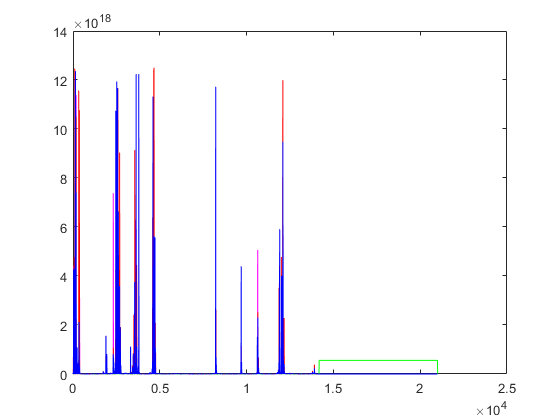


%%【计算A B C 浓度】

%%计算 c 码的浓度
c_total_c=zeros(size(t1));%% 10个比特，20秒钟，200个函数点 0-199;
c_total_c=concentration_calculate(c_total_c,encode_c,d_mobile,t1,M,D,v_drift,example_number);
values = spcrv([[t1(1) t1 t1(end)];[c_total_c(1) c_total_c c_total_c(end)]],3);
plot(values(1,:),values(2,:), 'm');
hold on
%【距离预测与阈值设置】
threshold=zeros(size(t1));
distance=zeros(size(t1));
detection_bit_total=zeros(size(t1));
count_c=0;
threshold(threshold>=0)=0.5*max(M./(4.*pi.*D.*t1).^(1.5).*exp(-(d_initial-v_drift*t1).^2./(4.*D.*t1)));
for i=1:1:length(c_total_c)-1
    if c_total_c(i)<threshold(i)&&c_total_c(i+1)>=threshold(i+1)
        i;
       for k=i+1:1:length(c_total_c)-1
           if c_total_c(k)>=threshold(k)&&c_total_c(k+1)<threshold(k+1)%【k-i>10防止出现噪声的细小峰值的影响】
              count_c=count_c+1;%【计数第几个C分子，以此来计算传输时间】
              [peak_concentration_c,index]=max(c_total_c(i+1:k));
              peak_position=i+index;
              detection_bit_total(peak_position)=3;%【求得峰值位置，在峰值位置上填3】
              [threshold,distance]=threshold_prediction(count_c,peak_position,threshold,distance,example_time,example_number,block_length,v,v_drift,t1,t2,D,M);%【计算峰值距离并预测阈值】
              break %%【跳出k的循环】
           end
       end
    end          
end
values = spcrv([[t1(1) t1 t1(end)];[threshold(1) threshold threshold(end)]],3);
plot(values(1,:),values(2,:), 'g');
hold on

%%【计算 a 码的浓度，并信号检测】
c_total_a=zeros(size(t1));%% 10个比特，20秒钟，200个函数点 0-199;
c_total_a=concentration_calculate(c_total_a,encode_a,d_mobile,t1,M,D,v_drift,example_number);
detection_bit_total=detection(detection_bit_total,c_total_a,threshold,1);
values = spcrv([[t1(1) t1 t1(end)];[c_total_a(1) c_total_a c_total_a(end)]],3);
plot(values(1,:),values(2,:), 'R');
hold on

%%【计算 b 码的浓度，并信号检测】
c_total_b=zeros(size(t1));%% 10个比特，20秒钟，200个函数点 0-199;
c_total_b=concentration_calculate(c_total_b,encode_b,d_mobile,t1,M,D,v_drift,example_number);
detection_bit_total=detection(detection_bit_total,c_total_b,threshold,2);
values = spcrv([[t1(1) t1 t1(end)];[c_total_b(1) c_total_b c_total_b(end)]],3);
plot(values(1,:),values(2,:), 'b');
hold on


%%把中间多余的0去掉
% detection_bit_total
index=find(detection_bit_total==0);
detection_bit_total(index)=[];
detection_bit_total

detection_bit_total =      3     2     1     1     1     2     1     2     2     2     3     2     1     1     1     2     2     2     2     2     3     2     2     2     1     1     1     2     2     2     3     2     2     1     1     2     1     2     2     1     3     1     2     1     2     2     1     1     1     2


for i=length(detection_bit_total):-1:1
    if detection_bit_total(i)~=3
       detection_bit_total(i)=[];
    else
        break
    end
end
detection_bit_total

detection_bit_total =      3     2     1     1     1     2     1     2     2     2     3     2     1     1     1     2     2     2     2     2     3     2     2     2     1     1     1     2     2     2     3     2     2     1     1     2     1     2     2     1     3     1     2     1     2     2     1     1     1     2



for i=1:1:block
    detection_bit_total=tianjia(detection_bit_total,block_length);
end
detection_bit_total

detection_bit_total =      3     2     1     1     1     2     1     2     2     2     3     2     1     1     1     2     2     2     2     2     3     2     2     2     1     1     1     2     2     2     3     2     2     1     1     2     1     2     2     1     3     1     2     1     2     2     1     1     1     2


for i=1:1:block
    detection_bit_total=shanchu(detection_bit_total,block_length);
end
detection_bit_total

detection_bit_total =      3     2     1     1     1     2     1     2     2     2     3     2     1     1     1     2     2     2     2     2     3     2     2     2     1     1     1     2     2     2     3     2     2     1     1     2     1     2     2     1     3     1     2     1     2     2     1     1     1     2



error=zeros(size(encode_a_b_c));
duibi=[encode_a_b_c;detection_bit_total;error]; %%对比一下源码与解码
for i=1:1:length(encode_a_b_c)
    if duibi(1,i)~=duibi(2,i)
       duibi(3,i)=duibi(1,i);
    end
end
duibi;
[errornumber,BER]=biterr(encode_a_b_c,detection_bit_total)

errornumber = 0

BER = 0

% catch 
% BER =1% 如果出错，误码率是1
% end 

      


delete(gcp('nocreate'))
profile viewer
toc

时间已过 816.266177 秒。


%%三种分子编码函数

function B=encode_abc(bit,patch_length)
    B = [3];
    n = length(bit); % 得到bit长度
    for i=1:n
      B=[B bit(i)];
        if mod(i,patch_length)==0
        B = [B 3];
        end
    end
end

%% 浓度计算引用的函数
function c_total=concentration_calculate(c_total,encode,d_mobile,t1,M,D,v_drift,example_number)
    parfor i=1:1:length(encode) %%遍历待发送比特
%     for i=1:1:length(encode) %%遍历待发送比特
    c_total=c_total+encode(i).*c_current(i,d_mobile,t1,M,D,v_drift,example_number);
    end
    %% 使用平均值取消掉NAN数据
    c_total(1)=0;
    c_total(isnan(c_total)==1)=(c_total(find(isnan(c_total)==1)-1)+c_total(find(isnan(c_total)==1)+1))/2;
    c_total((c_total<10^-10)==1)=0;
end

%% 浓度计算函数
function c_bit=c_current(i,d_mobile,t1,M,D,v_drift,example_number)
    c_bit=zeros(size(t1));
    if i==1
        for j=1:1:length(c_bit)
        c_bit(j)=M./(4.*pi.*D.*(t1(j))).^(1.5).*exp(-(d_mobile(j)-v_drift*t1(j)).^2./(4.*D.*t1(j)));
        end
    else %i~=1
    for j=1:1:(i-1)*example_number  %% 第i个发送的比特，前面（i-1）*20个数值都是0，后面按照菲克定律
        c_bit(j)=0;
    end
    for j=(i-1)*example_number+1:1:length(c_bit)
        k=j-example_number*(i-1);
        c_bit(j)=M./(4.*pi.*D.*(t1(k))).^(1.5).*exp(-(d_mobile(j)-v_drift*t1(k)).^2./(4.*D.*t1(k)));
    end   
    
    end
%     c_bit;
end
%%【距离预测与阈值设置函数】
function [threshold,distance]=threshold_prediction(count_c,peak_position,threshold,distance,example_time,example_number,patch_length,v,v_drift,t1,t2,D,M)
    peak_time_c=peak_position*example_time-(count_c-1)*(patch_length+1)*2;%【计算出C分子的传输时长】
    %【通过传输时长与峰值浓度计算距离】
    distance(peak_position)=(v_drift.^2*peak_time_c.^2+6*D*peak_time_c).^0.5;    %%【全用峰值时间反推实际距离，这是求导出来的结果】
    %【距离预测】
    for i=peak_position:1:peak_position+10*patch_length*example_number%%【在此设置了往后10个length的距离,减轻计算负担】
%     for i=peak_position:1:length(t1)
        distance(i+1)=distance(i)+v*example_time;
    end
    %【阈值设定】
    flag=ceil(peak_position/example_number);    
        for k=0:1:length(t1)/example_number-flag-1
            threshold(flag*example_number+example_number*k+1:flag*example_number+example_number*k+example_number)=max(M./(4.*pi.*D.*t2).^(1.5).*exp(-(distance(flag*example_number+example_number*k+example_number)-v_drift*t2).^2./(4.*D.*t2)));
        end
end
%%【a与b的信号检测函数】
function detection_bit_total=detection(detection_bit_total,c_total_a,threshold,type)
    for i=1:1:length(c_total_a)-1
        if c_total_a(i)<threshold(i)&&c_total_a(i+1)>=threshold(i+1)
           for k=i+1:1:length(c_total_a)-1
               if c_total_a(k)>=threshold(k)&&c_total_a(k+1)<threshold(k+1)
                  [peak_concentration_a,index]=max(c_total_a(i+1:k));
                  peak_position=i+index;
                  detection_bit_total(peak_position)=type;%【求得峰值位置，在峰值位置上填1】
                  break %%【跳出k的循环】
               end
           end
        end          
    end
end


function detection_bit_total= tianjia(detection_bit_total,patch_length)
    flag_c_tianjia=find(detection_bit_total==3);
    for i=1:1:length(flag_c_tianjia)-1   
         if flag_c_tianjia(i+1)-flag_c_tianjia(i)<patch_length+1 %% 如果小于了分块长度
             k=patch_length-(flag_c_tianjia(i+1)-flag_c_tianjia(i)-1);
             for n=1:1:k
                 detection_bit_total=[detection_bit_total(1:flag_c_tianjia(i+1)-1),1,detection_bit_total(flag_c_tianjia(i+1):end)];
             end
             break 
         end   
    end
end

function detection_bit_total= shanchu(detection_bit_total,patch_length)
    flag_c_shanchu=find(detection_bit_total==3);
    for i=1:1:length(flag_c_shanchu)-1   
         if flag_c_shanchu(i+1)-flag_c_shanchu(i)>patch_length+1 %% 如果大于了分块长度10
            flag_c_shanchu(i+1);
            k=(flag_c_shanchu(i+1)-flag_c_shanchu(i)-1)-patch_length;
            for n=1:1:k
              detection_bit_total(flag_c_shanchu(i)+n)=[];%% 注意是减n
              n;
            end
            break   
         end   
    end
end


